I = imread("car2.jpg");
I = rgb2gray(I);
I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
imshow(I);
hold on;
plot(sift.selectStrongest(3))
num = sift.selectStrongest(1)
[features, valid_points] = extractFeatures(I, sift);
plot(valid_points,'showOrientation',true);


rootFolder = 'cifar-100-matlab\CIFAR-100\TEST';
% categories = {'cup','dinosaur'};
categories = {'cup','dinosaur','forest','hamster'};
imds = imageDatastore(fullfile(rootFolder, categories), 'LabelSource', 'foldernames');
imds.ReadFcn = @readFunctionTrain;

% Change the number 50 to as many training images as you would like to use
% how does increasing the number of images change the 
% accuracy of the classifier?
[trainingSet, ~] = splitEachLabel(imds, 10, 'randomize'); 

% X = dataset of images
F = [];
ref = [];
numImages = numel(trainingSet.Files);

% preprocess the images and collect their SIFT features into a matrix
for i = 1:numImages
    I = im2gray(readimage(trainingSet,i));
    I = imresize(I, [256 256]);
    sift = detectSIFTFeatures(I);
    [features, sift_points] = extractFeatures(I, sift);
    F = [F features.'];
    ref = [ref repmat([i], 1, size(features,1))];
end

D = 'C:\Users\user\Documents\MATLAB\vLSH-master\grey4';
S = dir(fullfile(D,'*'));
N = setdiff({S([S.isdir]).name},{'.','..'}); % list of subfolders of D.
for ii = 1:numel(N)
    T = dir(fullfile(D,N{ii},'*')); % improve by specifying the file extension.
    C = {T(~[T.isdir]).name}; % files in subfolder.
    for jj = 1:numel(C)
        F = fullfile(D,N{ii},C{jj});
        currentimage = imread(F);
        images{jj} = currentimage;
    end
end


% construct LSH hash tables for F

Q = 5; % # of queries
K = 32;   % # of nearest neighbors to search for each query
L = 2;    % # of tables
M = 10;   % # of dimensions at projection space
W = 1000; % bucket width
T = 10;   % # of additional probing bins

% Construct index tables
lshStruct = lshConstruct(F, L, M, W);

Creating table 1/2
	Projecting data...
	545 buckets
	min / max size: 1 / 27
	mean / median: 2.409174e+00 / 1
Creating table 2/2
	Projecting data...
	546 buckets
	min / max size: 1 / 31
	mean / median: 2.404762e+00 / 1
Total time: 0.020188


[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(F(:, 1:Q), F, lshStruct, K, T);

Retrieving candidates from table 1
	-----> 0.039493 seconds
Retrieving candidates from table 2
	-----> 0.006999 seconds
Removing duplicate candidates...
	-----> 0.001120 seconds
Performing knn search...
	-----> 0.000293 seconds
Calculating candidate sizes...
	-----> 0.000333 seconds


queryM = zeros(size(idsMULTIPROBE));
for i = 1 : size(idsMULTIPROBE, 1)
    for j = 1 : size(idsMULTIPROBE, 2)
        if idsMULTIPROBE(i, j)>0
          queryM(i,j) = ref(:,idsMULTIPROBE(i, j));
        end
    end
end

ids = unique(queryM);
N = numel(ids);
count = zeros(N,1);
for k = 1:N
  count(k) = sum(sum(queryM==ids(k)));
end
%sorted = sort(count,1,'ascend')
ranks = sortrows([count ids],1,'descend')

ranks =     14    15
    13     1
    12    16
    10     2
     7     8
     7    10
     7    38
     6     4
     5    11
     5    17


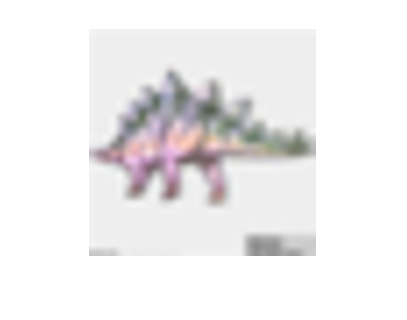

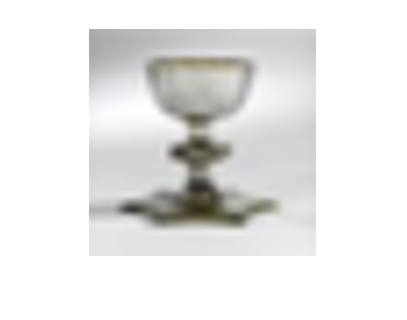

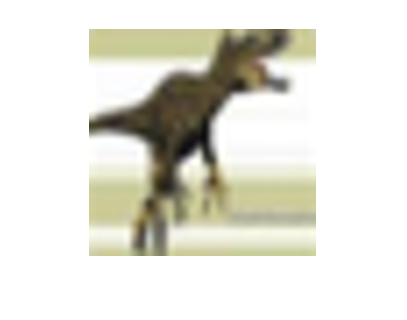

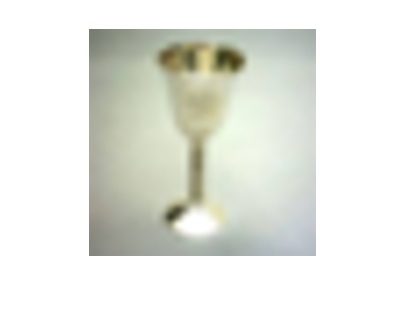

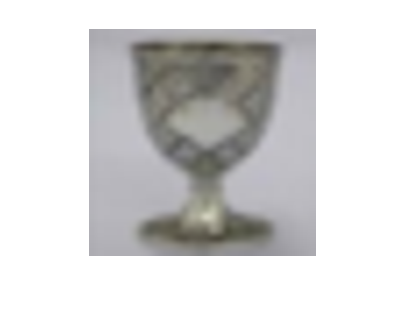

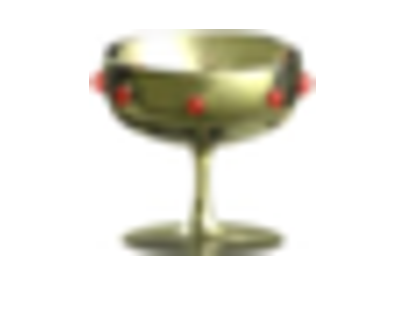

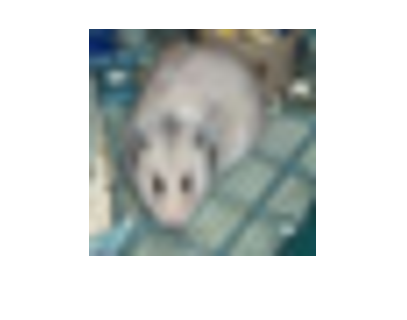

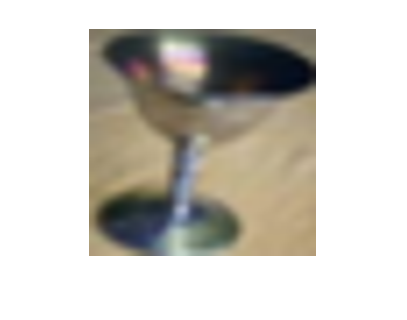

for pic = 1:length(ranks)
    I = readimage(trainingSet, ranks(pic, 2));
    figure,
    imshow(I);
end

I =   Image with properties:

           CData: [227×227×3 uint8]
    CDataMapping: 'direct'

  Show all properties


I = imshow(readimage(trainingSet, ranks(2, 2)))

% query for image
% query = image
I = imread(query);
% check if it is not already grey scale
if size(I,3)==3
    I = rgb2gray(I);
end

I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
[features, sift_points] = extractFeatures(I, sift);
Qfeatures = rot90(features);




% Perform simple LSH search on the first Q elements of X
[idsSIMPLE, cand_sizeSIMPLE, binsFound_ratiosSIMPLE] = lshSearch(Qfeatures, X, lshStruct, K);
% is the same with: [idsSIMPLE cand_sizeSIMPLE binsFound_ratiosSIMPLE] = lshSearch(X(:, 1:Q), X, lshStruct, K, 0);

% Perform multiprobe LSH search on the first Q elements of X
[idsMULTIPROBE, cand_sizeMULTIPROBE, binsFound_ratiosMULTIPROBE] = lshSearch(X(:, 1:Q), X, lshStruct, K, T);

% Perform brute force KNN on the first Q elements of X
% [~, idsTRUE] = knn(X(:, 1:Q), X, K);

% Compute recalls
% recallSIMPLE = compute_recall(idsTRUE, idsSIMPLE);
% recallMULTIPROBE = compute_recall(idsTRUE, idsMULTIPROBE);

% Compute selectivities (i.e. mean size of distinct candidates for each query)
% selectivitySIMPLE = sum(cand_sizeSIMPLE) / (Q * size(X, 2));
% selectivityMULTIPROBE = sum(cand_sizeMULTIPROBE) / (Q * size(X, 2));
